# Sprawozdanie z przedmiotu Modelowanie systemów dynamicznych.

Temat laboratoriów: Identyfikacja obiektu regulacji

Filip Pasternak, Grupa lab. 7, środa godz 13:45.

t = 1:1:60;


% A
% 2.1
k = 2.145;
T = 15.7;
theta = 7.7;

obiektA = tf([0 k], [T 1])

obiektA =
 
    2.145
  ----------
  15.7 s + 1
 
Continuous-time transfer function.



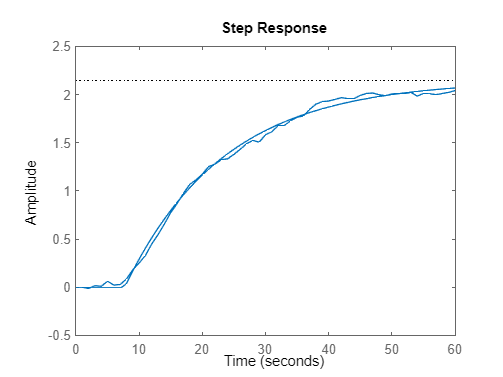

set(obiektA, 'outputDelay', theta)

figure
hold on
step(obiektA)
plot(t, y)
xlim([0 60])


% blad aproksymacji:
e = y - step(obiektA, t);
RMS = sum(e.^2)/length(e)

RMS = 0.0016

% 2.4
[parametry, blad] = fminsearch('ident',[1,1,1])

parametry =     2.1422   15.4254    8.0971


blad = 0.0015

obiektA = tf([0 parametry(1)], [parametry(2) 1])

obiektA =
 
     2.142
  -----------
  15.43 s + 1
 
Continuous-time transfer function.



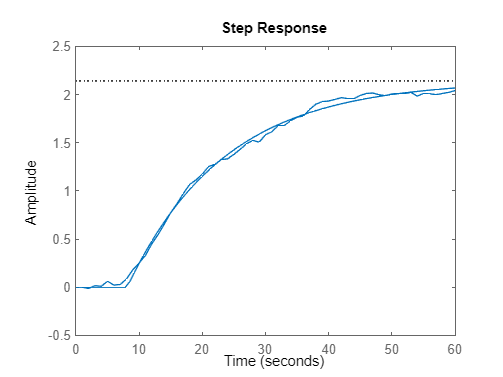

set(obiektA, 'outputDelay', parametry(3))

figure
hold on
step(obiektA)
plot(t, y)
xlim([0 60])

% B
% 2.4
T1 = 2;
T2 = 10;
k = 2;      %przykladowe parametry
[parametry_b, blad_b] = fminsearch('ident2',[1,1,1,1])

parametry_b =     2.1292    2.0541   14.8405    6.2836


blad_b = 0.0013

ans = 6.2836

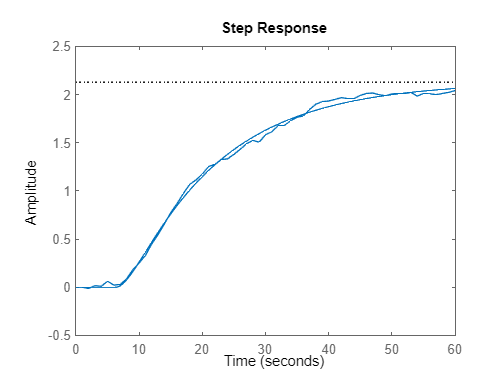

obiektB = tf([0 0 parametry_b(1)], conv([parametry_b(2) 1], [parametry_b(3) 1]));
set(obiektB, 'outputDelay', parametry_b(4))

figure
hold on
step(obiektB)
plot(t, y)
xlim([0 60])

% C

[parametry_c_rzad2, blad_c_rzad2] = fminsearch('ident3a', [1 1])

parametry_c_rzad2 =     0.0156    0.0844


blad_c_rzad2 = 0.0073

[parametry_c_rzad3, blad_c_rzad3] = fminsearch('ident3b', [1 1])

parametry_c_rzad3 =     0.0058    0.1411


blad_c_rzad3 = 0.0027

[parametry_c_rzad4, blad_c_rzad4] = fminsearch('ident3c', [1 1])

parametry_c_rzad4 =     0.0030    0.1967


blad_c_rzad4 = 0.0032

[parametry_c_rzad5, blad_c_rzad5] = fminsearch('ident3d', [1 1])

parametry_c_rzad5 =     0.0020    0.2522


blad_c_rzad5 = 0.0055

obiektC_rzad2 = zpk([], [-parametry_c_rzad2(2), -parametry_c_rzad2(2)],parametry_c_rzad2(1));

obiektC_rzad3 = zpk([], [-parametry_c_rzad3(2), -parametry_c_rzad3(2), -parametry_c_rzad3(2)],parametry_c_rzad3(1));
obiektC_rzad4 = zpk([], [-parametry_c_rzad4(2), -parametry_c_rzad4(2), -parametry_c_rzad4(2), -parametry_c_rzad4(2)],parametry_c_rzad4(1));
obiektC_rzad5 = zpk([], [-parametry_c_rzad5(2), -parametry_c_rzad5(2), -parametry_c_rzad5(2), -parametry_c_rzad5(2), -parametry_c_rzad5(2)],parametry_c_rzad5(1));

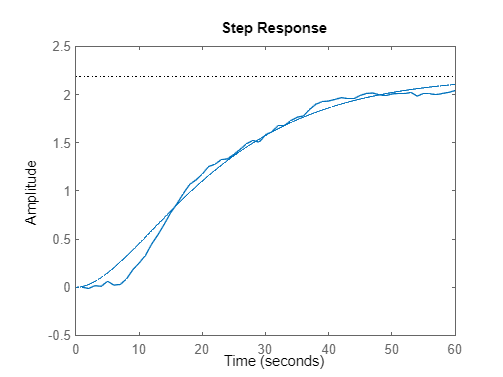

% obiekt rzedu 2
figure
hold on
step(obiektC_rzad2)
plot(t, y)
xlim([0 60])

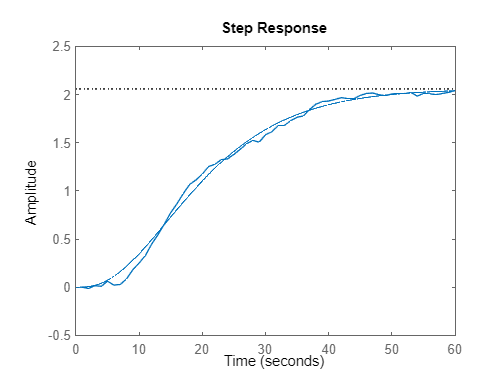

% obiekt rzedu 3
figure
hold on
step(obiektC_rzad3)
plot(t, y)
xlim([0 60])

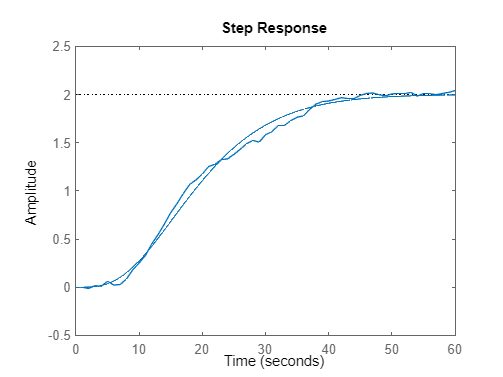

% obiekt rzedu 4
figure
hold on
step(obiektC_rzad4)
plot(t, y)
xlim([0 60])

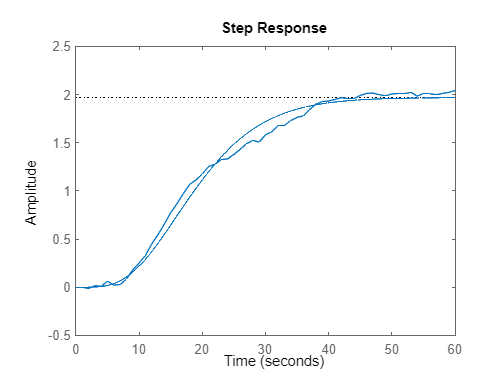

% obiekt rzedu 5
figure
hold on
step(obiektC_rzad5)
plot(t, y)
xlim([0 60])